# Try Different Classification Models

Instructions are in the task pane to the left. Complete and submit each task one at a time.

% Do not edit. This code loads and plots the data.
load letterdata.mat
traindata

traindata = 2907×26 table
    AspectRatio      MADX       MADY        AvgU       MADU         AvgV        MADV      CorrXY       CorrXP      CorrXU      CorrXV      CorrYP       CorrYU      CorrYV       CorrPU       CorrPV       CorrUV      NumXMin    NumXMax    NumYMin    NumYMax    NumUMin    NumUMax    NumVMin    NumVMax    Character
    ___________    ________    _______    ________    _______    __________    ______    ___

## Task 1

Your training data can introduce biases in your model. How are the 26 letters of the alphabet distributed in the handwriting training data?

**TASK**

Use the `histogram` function to make a histogram of the known letter classes (stored in the `Character` variable of the table `traindata`).

**Hint**

Pass `traindata.Character` as an input to the `histogram` function.

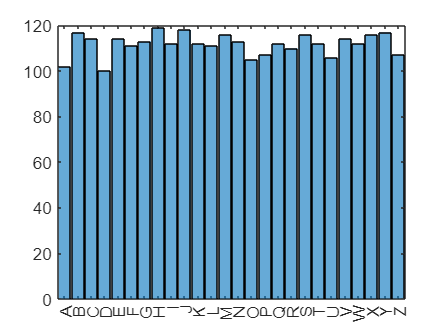

histogram(traindata.Character)

## Task 2

A boxplot is a simple way to visualize multiple distributions.

`boxplot``(``x``,``c``)`

This creates a plot where the boxes represent the distribution of the values of `x` for each of the classes in `c`. If the values of `x` are typically significantly different for one class than another, then `x` is a feature that can distinguish between those classes. The more features you have that can distinguish different classes, the more likely you are to be able to build an accurate classification model from the full data set.

**TASK**

Use the `boxplot` function to make a boxplot of the values of the `MADX` feature (mean absolute deviation of the horizontal position) for each letter. The known letter classes are stored in the variable called `Character`.

**Hint**

Pass `traindata.MADX` and `traindata.Character` as inputs to the `boxplot` function.

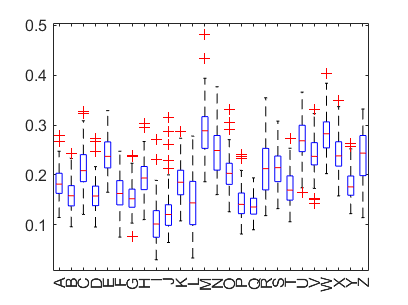

boxplot(traindata.MADX,traindata.Character)

## Further Practice

**Use the command** `classificationLearner` **to open the Classification Learner app.**

- Select `traindata` as the data to use.

- The app should correctly detect `Character` as the response variable to predict.

- Choose the default validation option.

- Select a model and click the **Train** button.

Try a few of the standard models with default options. **See if you can achieve at least 80% accuracy**.

Note that SVMs work on binary classification problems (i.e. where there are only two classes). To make SVMs work on this problem, the app is fitting many SVMs. These models will therefore be slow to train.

Similarly, ensemble methods work by fitting multiple models. These will also be slow to train.

classificationLearner